%% Load and Explore the Image Data
% Load the digit sample data as an |ImageDatastore| object.

digitDatasetPath = fullfile(matlabroot,'toolbox','nnet','nndemos', ...
        'nndatasets','DigitDataset');
digitData = imageDatastore(digitDatasetPath, ...
        'IncludeSubfolders',true,'LabelSource','foldernames');


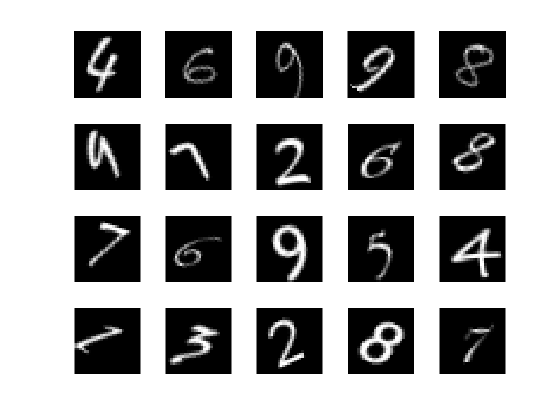

%% 
% Display some of the images in the datastore. 
figure;
perm = randperm(10000,20);
for i = 1:20
    subplot(4,5,i);
    imshow(digitData.Files{perm(i)});
end

figure;